# Numerical PSM

% clear,clc,close all;
L(1)=Link('revolute','d',0,'a',0,'alpha',pi/2,'offset',pi/2);
L(2)=Link('revolute','d',0,'a',0,'alpha',-pi/2,'offset',-pi/2);
L(3)=Link('prismatic','theta',0,'a',0,'alpha',pi/2,'offset',-0.4318);
L(4)=Link('revolute','d',0.4162,'a',0,'alpha',0,'offset',0);
L(5)=Link('revolute','d',0,'a',0,'alpha',-pi/2,'offset', -pi/2);
L(6)=Link('revolute','d',0,'a',0.0091,'alpha',-pi/2,'offset',-pi/2);

L(1).mdh=1;
L(2).mdh=1;
L(3).mdh=1;
L(4).mdh=1;
L(5).mdh=1;
L(6).mdh=1;

L1 = eye(3);
l = [1,2,3];
m = 1;
r = l./m;
I1 = L2I(L1,m,r);

L(1).I=I1;
L(1).r=r;
L(1).m=m;

L(2).I=I1;
L(2).r=r;
L(2).m=m;

L(2).I=I1;
L(2).r=r;
L(2).m=m;

L(3).I=I1;
L(3).r=r;
L(3).m=m;

L(4).I=I1;
L(4).r=r;
L(4).m=m;

L(5).I=I1;
L(5).r=r;
L(5).m=m;

L(6).I=I1;
L(6).r=r;
L(6).m=m;

grav = [0,0,-9.81];

L(3).qlim=[0,0.5]

 
L = 
Revolute(mod):  theta=q1   d=0           a=0           alpha=1.571       offset=1.571      
Revolute(mod):  theta=q2   d=0           a=0           alpha=-1.571      offset=-1.571     
Prismatic(mod): theta=0             d=q3 a=0           alpha=1.571       offset=-0.4318    
Revolute(mod):  theta=q4   d=0.4162      a=0           alpha=0           offset=0          
Revolute(mod):  theta=q5   d=0           a=0           alpha=-1.571      offset=-1.571     
Revolute(mod):  theta=q6   d=0           a=0.0091      alpha=-1.571      offset=-1.571     



PSM = SerialLink(L)

 
PSM = 
 
noname:: 6 axis, RRPRRR, modDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|          0|    -1.5708|    -1.5708|
|  3|          0|         q3|          0|     1.5708|    -0.4318|
|  4|         q4|     0.4162|          0|          0|          0|
|  5|         q5|          0|          0|    -1.5708|    -1.5708|
|  6|         q6|          0|     0.0091|    -1.5708|    -1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
 



L(3).qlim=[0,0.5]

 
L = 
Revolute(mod):  theta=q1   d=0           a=0           alpha=1.571       offset=1.571      
Revolute(mod):  theta=q2   d=0           a=0           alpha=-1.571      offset=-1.571     
Prismatic(mod): theta=0             d=q3 a=0           alpha=1.571       offset=-0.4318    
Revolute(mod):  theta=q4   d=0.4162      a=0           alpha=0           offset=0          
Revolute(mod):  theta=q5   d=0           a=0           alpha=-1.571      offset=-1.571     
Revolute(mod):  theta=q6   d=0           a=0.0091      alpha=-1.571      offset=-1.571     



PSM = SerialLink(L,'name','PSM')

 
PSM = 
 
PSM:: 6 axis, RRPRRR, modDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|          0|    -1.5708|    -1.5708|
|  3|          0|         q3|          0|     1.5708|    -0.4318|
|  4|         q4|     0.4162|          0|          0|          0|
|  5|         q5|          0|          0|    -1.5708|    -1.5708|
|  6|         q6|          0|     0.0091|    -1.5708|    -1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
 



% PSM.plot([0,0,0,0,0,0])

q=[pi/6, pi/4, 0.3, pi/5, pi/3, pi/4]

q =     0.5236    0.7854    0.3000    0.6283    1.0472    0.7854


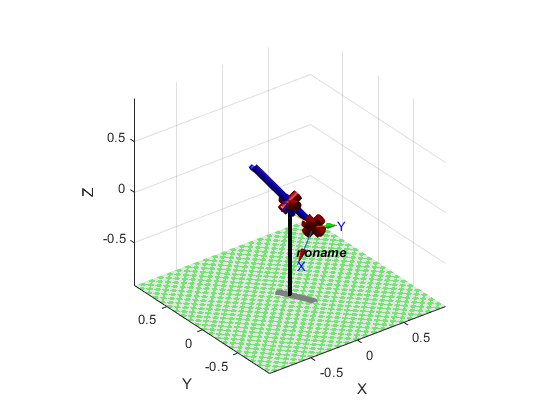

PSM.plot(q)

Tr=PSM.fkine(q)

 

Tr = 
   -0.7104   -0.0134   -0.7037   0.09589
   -0.3064   -0.8942    0.3263   -0.2088
   -0.6336    0.4475    0.6311   -0.1754
         0         0         0         1


PSM.ikine(Tr, 'q0', [pi/6, pi/4, 0.3, 0, pi/3, pi/4])

ans =     0.5236    0.7854    0.3000    0.6283    1.0472    0.7854


PSM.ikine(Tr, 'q0', rand(1,6))

ans =     0.5236    0.7854    0.3000    0.6283    1.0472    0.7854


q = [0.47684083488344164 0.8281161799765671 0.3095282096642102 0.6622877604441374 -2.147996414799056 2.3559716584364914]

q =     0.4768    0.8281    0.3095    0.6623   -2.1480    2.3560


Tr2  = PSM.fkine(q)

 

Tr2 = 
    0.7104   -0.0134    0.7037   0.09589
    0.3064   -0.8942   -0.3263   -0.2088
    0.6337    0.4474   -0.6311   -0.1754
         0         0         0         1


Tr0=PSM.fkine([0,0,0,0,0,0])

 

Tr0 = 
        -1         0         0         0
         0         0        -1         0
         0        -1         0    0.0065
         0         0         0         1


PSM.ikine(Tr0, 'q0', rand(1,6))


ans =

     []



% Jacobian
q=[pi/6, pi/4, 0.3, pi/5, pi/3, pi/4]

q =     0.5236    0.7854    0.3000    0.6283    1.0472    0.7854


T = PSM.fkine(q).T;
R = T(1:3,1:3)

R =    -0.7104   -0.0134   -0.7037
   -0.3064   -0.8942    0.3263
   -0.6336    0.4475    0.6311


eul = tr2eul(T)

eul =     2.7074    0.8878    0.6148


% convert to ZYZ euler angles
phi = atan2(R(2,3), R(1,3))

phi = 2.7074

psi = atan2(R(3,2), -R(3,1))

psi = 0.6148

theta = atan2(sqrt(R(1,3)^2 + R(2,3)^2), R(3,3))

theta = 0.8878


% Ta
Ta = [0, -sin(phi), cos(phi)*sin(theta);
    0, cos(phi), sin(phi)*sin(theta);
    1, 0, cos(theta)]

Ta =          0   -0.4207   -0.7037
         0   -0.9072    0.3263
    1.0000         0    0.6311


J0 = PSM.jacob0(q)

J0 =     0.1754   -0.1044    0.3536   -0.0039   -0.0064         0
   -0.0000   -0.1998   -0.7071    0.0033    0.0030         0
    0.0959    0.1808   -0.6124   -0.0060    0.0057         0
   -0.0000   -0.8660         0    0.3536   -0.4928   -0.7037
   -1.0000    0.0000         0   -0.7071    0.4156    0.3263
   -0.0000   -0.5000         0   -0.6124   -0.7645    0.6311


Jeuler = PSM.jacob0(q, 'eul')

Jeuler =     0.1754   -0.1044    0.3536   -0.0039   -0.0064         0
   -0.0000   -0.1998   -0.7071    0.0033    0.0030         0
    0.0959    0.1808   -0.6124   -0.0060    0.0057         0
    0.3423   -1.1392         0   -0.1094   -1.2704   -0.0000
    0.9072    0.3643         0    0.4927   -0.1697         0
   -0.5423    1.0128         0   -0.7970    0.8018    1.0000


Jrpy = PSM.jacob0(q, 'rpy')

Jrpy =     0.1754   -0.1044    0.3536   -0.0039   -0.0064         0
   -0.0000   -0.1998   -0.7071    0.0033    0.0030         0
    0.0959    0.1808   -0.6124   -0.0060    0.0057         0
   -0.5120    0.5934         0    0.3648    1.1201   -0.5820
    0.9182    0.1980         0    0.8918   -0.0788   -0.5496
    0.3244   -1.2421         0    0.1224   -1.2026   -0.3350


myJ0 = getGeometricJacobianPSM(q);
myJeuler = myJ0;
myJeuler(4:6,:) = [zeros(3,3),Ta^(-1)]*myJ0

myJeuler =     0.1754   -0.1044    0.3536   -0.0039   -0.0064         0
         0   -0.1998   -0.7071    0.0033    0.0030         0
    0.0959    0.1808   -0.6124   -0.0060    0.0057         0
    0.3423   -1.1392         0   -0.1094   -1.2704   -0.0000
    0.9072    0.3643         0    0.4927   -0.1697    0.0000
   -0.5423    1.0128         0   -0.7970    0.8018    1.0000


immse(J0, myJ0)

ans = 1.3029e-32

immse(myJeuler, Jeuler)

ans = 2.5360e-32

% convert to XYZ RPY angles
%% case 1
rpy = tr2rpy(T)

rpy =     0.6167    0.6863   -2.7343


% phi = Z
phi = atan2(R(2,1), R(1,1))

phi = -2.7343

% theta = Y
theta = atan2(-R(3,1), sqrt(R(3,2)^2 + R(3,3)^2))

theta = 0.6863

% psi = X
psi = atan2(R(3,2), R(3,3))

psi = 0.6167



% X is roll:
Ta = [	
    sin(theta), 0, 1;
    -cos(theta)*sin(phi), cos(phi), 0;
    cos(theta)*cos(phi), sin(phi), 0;
    ];

J0 = PSM.jacob0(q)

J0 =     0.1754   -0.1044    0.3536   -0.0039   -0.0064         0
   -0.0000   -0.1998   -0.7071    0.0033    0.0030         0
    0.0959    0.1808   -0.6124   -0.0060    0.0057         0
   -0.0000   -0.8660         0    0.3536   -0.4928   -0.7037
   -1.0000    0.0000         0   -0.7071    0.4156    0.3263
   -0.0000   -0.5000         0   -0.6124   -0.7645    0.6311


Jrpy = PSM.jacob0(q, 'rpy')

Jrpy =     0.1754   -0.1044    0.3536   -0.0039   -0.0064         0
   -0.0000   -0.1998   -0.7071    0.0033    0.0030         0
    0.0959    0.1808   -0.6124   -0.0060    0.0057         0
   -0.5120    0.5934         0    0.3648    1.1201   -0.5820
    0.9182    0.1980         0    0.8918   -0.0788   -0.5496
    0.3244   -1.2421         0    0.1224   -1.2026   -0.3350


myJ0 = getGeometricJacobianPSM(q);
myJrpy = myJ0;
myJrpy(4:6,:) = [zeros(3,3),Ta^(-1)]*myJ0

myJrpy =     0.1754   -0.1044    0.3536   -0.0039   -0.0064         0
         0   -0.1998   -0.7071    0.0033    0.0030         0
    0.0959    0.1808   -0.6124   -0.0060    0.0057         0
   -0.5120    0.5934         0    0.3648    1.1201   -0.5820
    0.9182    0.1980         0    0.8918   -0.0788   -0.5496
    0.3244   -1.2421         0    0.1224   -1.2026   -0.3350


immse(myJrpy, Jrpy)

ans = 1.9395e-32

J = getJacobianPSM(q, 'rpy')

J =     0.1754   -0.1044    0.3536   -0.0039   -0.0064         0
         0   -0.1998   -0.7071    0.0033    0.0030         0
    0.0959    0.1808   -0.6124   -0.0060    0.0057         0
   -0.5120    0.5934         0    0.3648    1.1201   -0.5820
    0.9182    0.1980         0    0.8918   -0.0788   -0.5496
    0.3244   -1.2421         0    0.1224   -1.2026   -0.3350


test = [1,2,3,4,5,6]

test =      1     2     3     4     5     6


tau = PSM.rne([1,2,3,4,5,6],[1,2,3,4,5,6],[1,2,3,4,5,6],'gravity',[0,0,9.81])

tau =    43.0761  309.9937 -153.1861  238.8928 -153.2094   20.8622
